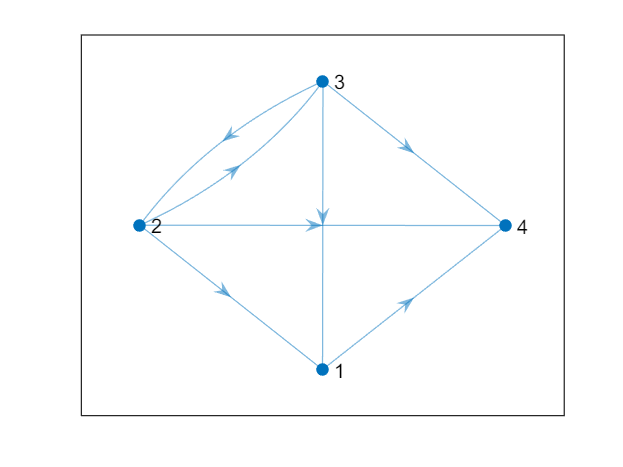


%% Figure 3.1
% s  = [1 2 3 4 4 4]
% t  = [3 3 4 1 2 3]

% Example

% Figure 3.2
s = [1 2 2 2 3 3 3];
t = [4 1 3 4 1 2 4];
 
% %Figure 3.4
% s = [1 1 2 2 3 3 4 5 5 6 6 7 7 8 8 8];
% t = [2 3 1 5 2 8 3 4 8 5 4 6 4 1 4 7];

G = digraph(s,t);
plot(G)


pi = pageRank(G)

O =      1
     3
     3
     0


H =      0     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0     0


H =          0         0         0    1.0000
    0.3333         0    0.3333    0.3333
    0.3333    0.3333         0    0.3333
       NaN       NaN       NaN       NaN


indicator = 4×1 logical 배열
   0
   0
   0
   1


H =          0         0         0    1.0000
    0.3333         0    0.3333    0.3333
    0.3333    0.3333         0    0.3333
         0         0         0         0


H =          0         0         0    1.0000
    0.3333         0    0.3333    0.3333
    0.3333    0.3333         0    0.3333
    0.2500    0.2500    0.2500    0.2500


G_mat =     0.0375    0.0375    0.0375    0.8875
    0.3208    0.0375    0.3208    0.3208
    0.3208    0.3208    0.0375    0.3208
    0.2500    0.2500    0.2500    0.2500


pi =     0.2323    0.1615    0.1615    0.4448


pi =     0.2235    0.1778    0.1778    0.4210


pi =     0.2277    0.1773    0.1773    0.4177


pi =     0.2267    0.1765    0.1765    0.4203


pi =     0.2268    0.1768    0.1768    0.4195


pi =     0.2268    0.1768    0.1768    0.4196


pi =     0.2268    0.1768    0.1768    0.4196





    theta = 0.85; 
    epsilon = 0.001;

    n = numnodes(G);        % number of nodes
    A = adjacency(G);
    c = full(A);            % adjacency matrix, 
                            % c(i,j) == 1 if i and j are connnected

    % calculate out degree
    O = sum(c,2); %행을 더한다.
    O(isnan(O)) = 0

O =      1
     3
     3
     0


    %% compute H
    H = zeros(n,n) 

H =      0     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0     0


    H = c./O    

H =          0         0         0    1.0000
    0.3333         0    0.3333    0.3333
    0.3333    0.3333         0    0.3333
       NaN       NaN       NaN       NaN



    %% handle dangling nodes
    indicator = ~O

indicator = 4×1 logical 배열
   0
   0
   0
   1


    H(isnan(H)) = 0

H =          0         0         0    1.0000
    0.3333         0    0.3333    0.3333
    0.3333    0.3333         0    0.3333
         0         0         0         0


    H = H + (1/n).*(indicator)*(ones(n,1)')%% add randomization (using theta)

H =          0         0         0    1.0000
    0.3333         0    0.3333    0.3333
    0.3333    0.3333         0    0.3333
    0.2500    0.2500    0.2500    0.2500


    
    %% Add randomization
    G_mat= theta*H+(1-theta).*(1/n).*(ones(n,n)) 

G_mat =     0.0375    0.0375    0.0375    0.8875
    0.3208    0.0375    0.3208    0.3208
    0.3208    0.3208    0.0375    0.3208
    0.2500    0.2500    0.2500    0.2500



    % initilize pi
    pi = 1/n * ones(1,n);
    
    %% run PageRank
    error = 1;
    while error > epsilon
        prev_pi = pi;
        pi = (prev_pi)*(G_mat)
        % update error
        error = sum(abs(pi-prev_pi));
    end

pi =     0.2323    0.1615    0.1615    0.4448
